clear all


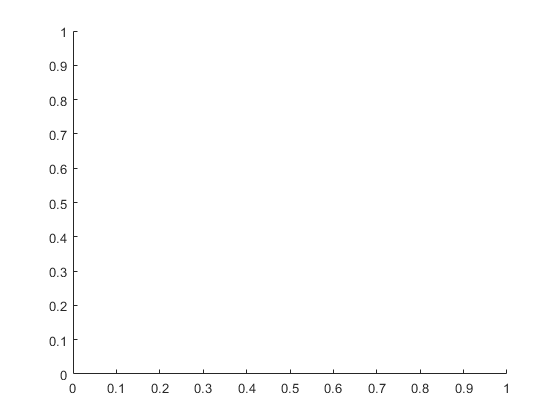

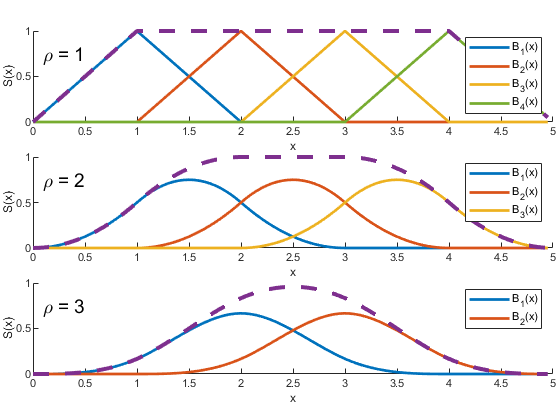

t = (0:0.01:0.99)';
colr = get(gca,'colororder');
fig=figure;

n=1;
m=5;
[un] = basisvectors(t,n,m);

subplot(3,1,1)
hold on
plot(t*5,un{1}(:,2:4),'LineWidth',2)
plot(t*5,un{1}(:,5:5),'LineWidth',2,"Color",colr(5,:))
plot(t*5,sum(un{1}(:,2:5),2),'--','LineWidth',3,'HandleVisibility','off',"Color",colr(4,:))
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','B_{3}(x)','B_{4}(x)','FontSize',8)
colr = get(gca,'colororder');
txt = '\rho = 1';
text(0.1,0.75,txt,'FontSize',14)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

n=2;
m=5;
[un] = basisvectors(t,n,m);
subplot(3,1,2)
hold on
plot(t*5,un{1}(:,3:5),'LineWidth',2)
plot(t*5,sum(un{1}(:,3:5),2),'--','LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','B_{3}(x)','FontSize',8)
txt = '\rho = 2';
text(0.1,0.75,txt,'FontSize',14)


ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

n=3;
m=5;
[un] = basisvectors(t,n,m);
subplot(3,1,3)
hold on
plot(t*5,un{1}(:,4:5),'LineWidth',2)
plot(0,'--','LineWidth',3,'HandleVisibility','off')
plot(t*5,sum(un{1}(:,4:5),2),'--','LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','FontSize',8)
txt = '\rho = 3';
text(0.1,0.75,txt,'FontSize',14)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

print(fig,'figures/bsplines','-depsc')

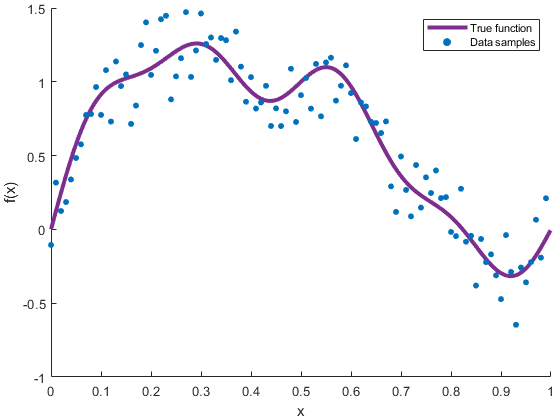

tt = (0:0.001:0.999)';

rng(1)
figz=figure;

% output = sin(2*pi*t)+ 0.5*sin(4*pi*t)+0.25*sin(8*pi*t)+0.125*sin(16*pi*t);
output = sin(pi*t)+ 0.5*sin(2*pi*t)+0.25*sin(4*pi*t)+0.125*sin(8*pi*t);
outputplot = sin(pi*tt)+ 0.5*sin(2*pi*tt)+0.25*sin(4*pi*tt)+0.125*sin(8*pi*tt);
% outputnoise = output + 0.25*randn(size(output))

outputnoise = addnoise(output,10);

hold on
plot(tt,outputplot,'color',colr(4,:),'LineWidth',3)
scatter(t,outputnoise,20,colr(1,:),'filled')
hold off

xlabel('x')
ylabel('f(x)')
legend('True function','Data samples','FontSize',8)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

print(figz,'figures/true','-depsc')


iter = 1

iter = 1


figoz = figure

figoz =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 56
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


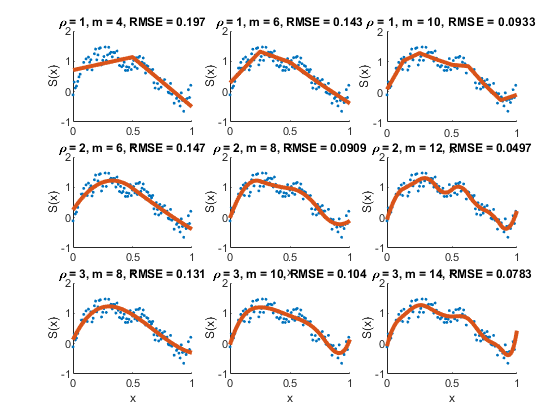


for n=[1 2 3]
    for m=[2 4 8]

subplot(3,3,iter)

[un] = basisvectors(t,n,m);
[unt] = basisvectors(tt,n,m);

A = un{1};
At = unt{1};

g=pinv(A'*A)*(A'*outputnoise);

y = A*g;
yplot = At*g;

RMSE = sqrt(immse(y,output));

hold on
% plot(t,output,'LineWidth',3)
scatter(t,outputnoise,5,'filled')
plot(tt,yplot,'color',colr(2,:),'LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
% legend('True','Noisy samples','FontSize',8)
title(['\rho = ' num2str(n) ', m = ' num2str(m+2*n) ', RMSE = ' num2str(RMSE,3)])

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

iter = iter+1;
    end
end

print(figoz,'figures/experiment','-depsc')

t([1:40 60:end])

ans =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


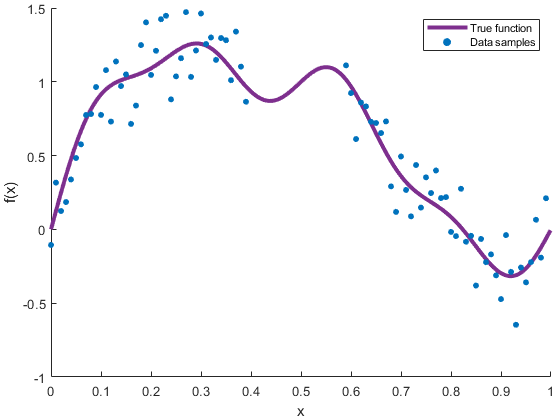

figoro = figure;
hold on
plot(tt,outputplot,'color',colr(4,:),'LineWidth',3)
scatter(t([1:40 60:end]),outputnoise([1:40 60:end]),20,colr(1,:),'filled')
hold off

xlabel('x')
ylabel('f(x)')
legend('True function','Data samples','FontSize',8)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

print(figoro,'figures/regtrue','-depsc')



n=3

n = 3

m=17

m = 17


tr = (0:0.001:0.999)';
iter = 1

iter = 1


figoz = figure

figoz =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 58
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


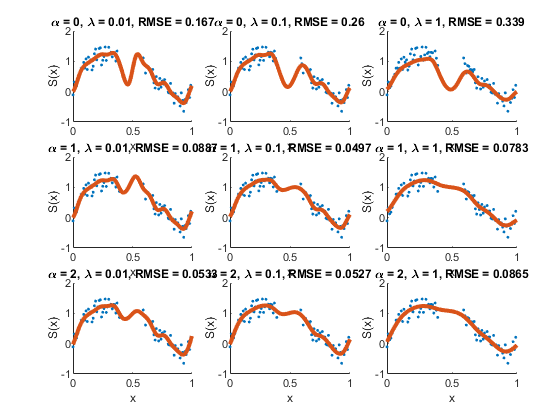


for difforder=[0 1 2]
    for lambda=[0.01 0.1 1]



        if difforder == 0
            PP=eye(n+m);
        else
            P = diff(eye(n+m),difforder);
            PP = P'*P;
        end
        
subplot(3,3,iter)

[un] = basisvectors(t([1:40 60:end]),n,m);
[unt] = basisvectors(tt,n,m);

A = un{1};
At = unt{1};

g=pinv(A'*A+ lambda*PP)*(A'*outputnoise([1:40 60:end]));

y = A*g;
yplot = At*g;

RMSE = sqrt(immse(outputplot,yplot));

hold on
% plot(t,output,'LineWidth',3)
scatter(t([1:40 60:end]),outputnoise([1:40 60:end]),5,'filled')
plot(tt,yplot,'color',colr(2,:),'LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
% legend('True','Noisy samples','FontSize',8)
title(['\alpha = ' num2str(difforder) ', \lambda = ' num2str(lambda) ', RMSE = ' num2str(RMSE,3)])

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

iter = iter+1;
    end
end

print(figoz,'figures/regexperiment','-depsc')





tt = (0:0.001:0.999)';

rng(1)
figz=figure;

% output = sin(2*pi*t)+ 0.5*sin(4*pi*t)+0.25*sin(8*pi*t)+0.125*sin(16*pi*t);
outputplot = sin(2*pi*tt)+ 0.5*sin(6*pi*tt-1)+0.25*sin(4*pi*tt)+0.125*sin(8*pi*tt);
output= outputplot(1:20:end)

output =    -0.4207
   -0.0440
    0.3529
    0.7293
    1.0491
    1.2860
    1.4261
    1.4689
    1.4255
    1.3150


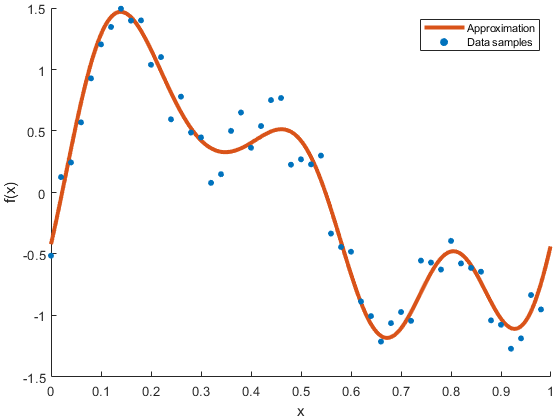

iter = 1

figoz =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 60
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


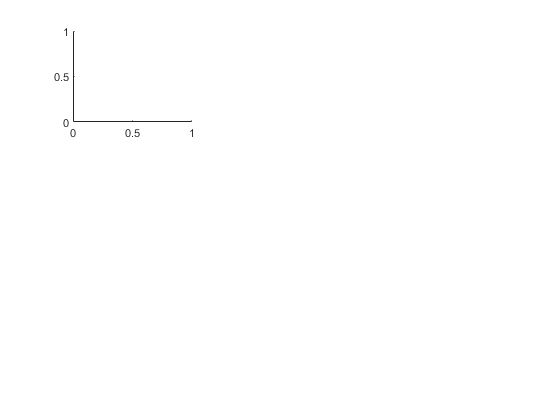

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.


% outputnoise = output + 0.25*randn(size(output))

outputnoise = addnoise(output,15);

hold on
plot(tt,outputplot,'color',colr(2,:),'LineWidth',3)
scatter(t(1:2:end),outputnoise,20,colr(1,:),'filled')
hold off

xlabel('x')
ylabel('f(x)')
legend('Approximation','Data samples','FontSize',8)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

print(figz,'figures/true','-depsc')